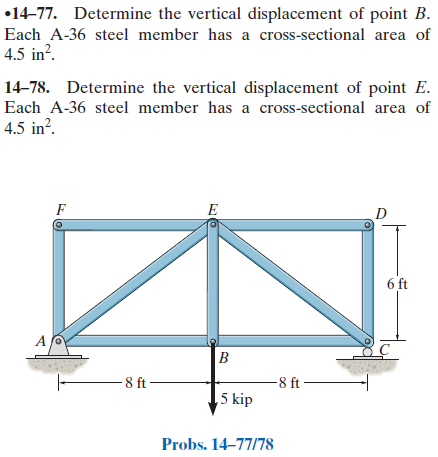

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-77P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-77P-solution-9780136022305) (problem 14-77)

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-78P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-14-problem-78P-solution-9780136022305) (problem 14-78)

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# joint data

theta = atand(sym(6/8))*u.deg;
jointA = [0 0]*u.ft;
jointB = [8 0]*u.ft;
jointC = [16 0]*u.ft;
jointD = [16 6]*u.ft;
jointE = [8 6]*u.ft;
jointF = [0 6]*u.ft;

# member data

E = 29e3*u.ksi;
A = 4.5*u.in^2;

# truss

t = Truss;
t = t.add('reaction', 'Ra', {'Rax' 'Ray'}, jointA);
t = t.add('reaction', 'Rc', {0 'Rcy'}, jointC);
t = t.add('concentrated', 'Pb', [0 -5]*u.kip, jointB);
t = t.add('joint', 'A', jointA);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', jointC);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', jointE);
t = t.add('joint', 'F', jointF);
t = t.add('member', 'Fab', jointA, jointB, E, A);
t = t.add('member', 'Fae', jointA, jointE, E, A);
t = t.add('member', 'Faf', jointA, jointF, E, A);
t = t.add('member', 'Fbc', jointB, jointC, E, A);
t = t.add('member', 'Fbe', jointB, jointE, E, A);
t = t.add('member', 'Fce', jointC, jointE, E, A);
t = t.add('member', 'Fcd', jointC, jointD, E, A);
t = t.add('member', 'Fde', jointD, jointE, E, A);
t = t.add('member', 'Fef', jointE, jointF, E, A);

# solution

[us ua ms ma ls la] = t.solve('Mode', 'factor');

# joint displacements

ua_vpa = vpa(ua, 3) %#ok<NASGU> 

$$ua\_vpa = \left(\begin{array}{cc} \mathrm{uA} & 0\\ \mathrm{vA} & 0\\ \mathrm{uB} & 0.00245\,\mathrm{in}\\ \mathrm{vB} & -0.0124\,\mathrm{in}\\ \mathrm{uC} & 0.0049\,\mathrm{in}\\ \mathrm{vC} & 0\\ \mathrm{uD} & 0.00245\,\mathrm{in}\\ \mathrm{vD} & 0\\ \mathrm{uE} & 0.00245\,\mathrm{in}\\ \mathrm{vE} & -0.00966\,\mathrm{in}\\ \mathrm{uF} & 0.00245\,\mathrm{in}\\ \mathrm{vF} & 0 \end{array}\right)$$

# forces on the truss

ma_f_m_vpa = vpa(ma.f.m, 3) %#ok<NASGU> 

$$ma\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & 3.33\,\mathrm{kip}\\ \mathrm{Fae} & -4.17\,\mathrm{kip}\\ \mathrm{Faf} & 0\\ \mathrm{Fbc} & 3.33\,\mathrm{kip}\\ \mathrm{Fbe} & 5.0\,\mathrm{kip}\\ \mathrm{Fce} & -4.17\,\mathrm{kip}\\ \mathrm{Fcd} & 0\\ \mathrm{Fde} & 0\\ \mathrm{Fef} & 0 \end{array}\right)$$

la_f_c_vpa = vpa(la.f.c) %#ok<NASGU> 

$$la\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 2.5\,\mathrm{kip} & 0\\ \mathrm{Rc} & 0 & 2.5\,\mathrm{kip} & 0\\ \mathrm{Pb} & 0 & -5.0\,\mathrm{kip} & 0 \end{array}\right)$$

ma_f_c_vpa = vpa(ma.f.c, 3) %#ok<NASGU> 

$$ma\_f\_c\_vpa = \left(\begin{array}{cccc} \mathrm{Fab} & 3.33\,\mathrm{kip} & 0 & 0\\ \mathrm{Fae} & -3.33\,\mathrm{kip} & -2.5\,\mathrm{kip} & 0\\ \mathrm{Faf} & 0 & 0 & 0\\ \mathrm{Fbc} & 3.33\,\mathrm{kip} & 0 & 0\\ \mathrm{Fbe} & 0 & 5.0\,\mathrm{kip} & 0\\ \mathrm{Fce} & 3.33\,\mathrm{kip} & -2.5\,\mathrm{kip} & 0\\ \mathrm{Fcd} & 0 & 0 & 0\\ \mathrm{Fde} & 0 & 0 & 0\\ \mathrm{Fef} & 0 & 0 & 0 \end{array}\right)$$

la_f_m_vpa = vpa(la.f.m) %#ok<NASGU> 

$$la\_f\_m\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & 2.5\,\mathrm{kip}\\ \mathrm{Rc} & 2.5\,\mathrm{kip}\\ \mathrm{Pb} & 5.0\,\mathrm{kip} \end{array}\right)$$

# moments on the truss

ma_m_m = ma.m.m %#ok<NASGU> 

$$ma\_m\_m = \left(\begin{array}{cc} \mathrm{Fab} & 0\\ \mathrm{Fae} & 0\\ \mathrm{Faf} & 0\\ \mathrm{Fbc} & 0\\ \mathrm{Fbe} & 40\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fce} & 40\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fcd} & 0\\ \mathrm{Fde} & 0\\ \mathrm{Fef} & 0 \end{array}\right)$$

la_m_c = la.m.c %#ok<NASGU> 

$$la\_m\_c = \left(\begin{array}{cccc} \mathrm{Ra} & 0 & 0 & 0\\ \mathrm{Rc} & 0 & 0 & 40\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pb} & 0 & 0 & -40\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

ma_m_c = ma.m.c %#ok<NASGU> 

$$ma\_m\_c = \left(\begin{array}{cccc} \mathrm{Fab} & 0 & 0 & 0\\ \mathrm{Fae} & 0 & 0 & 0\\ \mathrm{Faf} & 0 & 0 & 0\\ \mathrm{Fbc} & 0 & 0 & 0\\ \mathrm{Fbe} & 0 & 0 & 40\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fce} & 0 & 0 & -40\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Fcd} & 0 & 0 & 0\\ \mathrm{Fde} & 0 & 0 & 0\\ \mathrm{Fef} & 0 & 0 & 0 \end{array}\right)$$

la_m_m = la.m.m %#ok<NASGU> 

$$la\_m\_m = \left(\begin{array}{cc} \mathrm{Ra} & 0\\ \mathrm{Rc} & 40\,\mathrm{ft}\,\mathrm{kip}\\ \mathrm{Pb} & 40\,\mathrm{ft}\,\mathrm{kip} \end{array}\right)$$

# clean up

assume(old_assum);
clear old_assum;
clear ua_vpa;
clear ma_f_m_vpa la_f_c_vpa ma_f_c_vpa la_f_m_vpa;
clear ma_m_m la_m_c ma_m_c la_m_m;